%DEMO_ART Demonstrates the use of, and results from, the ART methods
%
% This script illustrates the use of the ART methods Kaczmarz, symmetric
% Kaczmarz, and randomized Kaczmarz.
%
% The script creates a parallel-beam CT test problem and solves it with the
% ART methods.  The exact image and the results from the methods are shown.
%
% See also: demo_cart, demo_constraints, demo_custom_all, demo_matrixfree,
% demo_relaxpar, demo_sirt, demo_stoprules, demo_training.

% Code written by: Per Christian Hansen, Jakob Sauer Jorgensen, and 
% Maria Saxild-Hansen, 2010-2017.

% This file is part of the AIR Tools II package and is distributed under
% the 3-Clause BSD License. A separate license file should be provided as
% part of the package. 
% 
% Copyright 2017 Per Christian Hansen, Technical University of Denmark and
% Jakob Sauer Jorgensen, University of Manchester.

clear, clc
fprintf(1,'Starting demo_art:\n\n');

Starting demo_art:




% Set the parameters for the test problem.
N = 50;           % The image is N-times-N..
theta = 0:2:178;  % No. of used angles.
p = 75;           % No. of parallel rays.
k = 10;           % Number of iterations.

fprintf(1,'Creating a parallel-beam tomography test problem\n');

Creating a parallel-beam tomography test problem


fprintf(1,'with N = %2.0f, theta = %1.0f:%1.0f:%3.0f, and p = %2.0f.',...
    [N,theta(1),theta(2)-theta(1),theta(end),p]);

with N = 50, theta = 0:2:178, and p = 75.

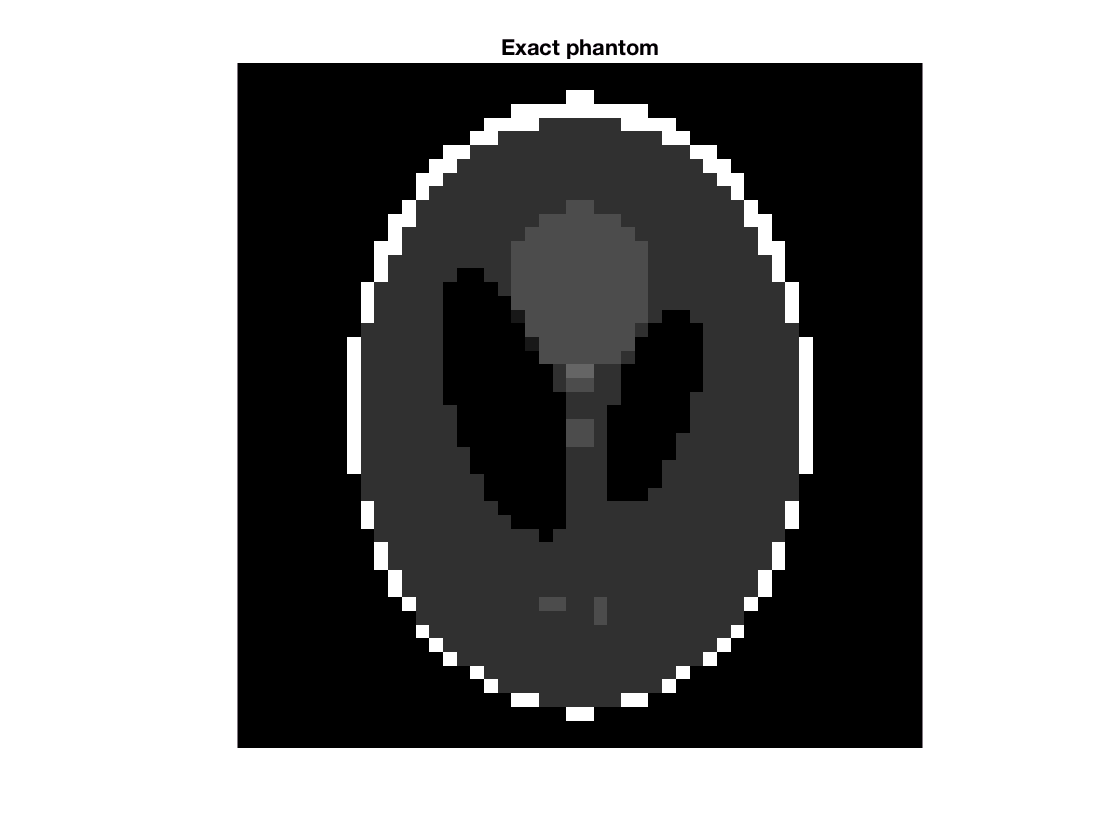


% Create the test problem.
[A,b,x] = paralleltomo(N,theta,p);

% Show the exact solution.
figure(1), clf
subplot()
% subplot(2,2,1)
imagesc(reshape(x,N,N)), colormap gray, axis image off
c = caxis;
title('Exact phantom')

x0 = zeros(N ^ 2, 1);
fprintf(1,'\n\n');

## Perform the Kaczmarz iterations.

fprintf(1,'Perform k = %2.0f iterations with Kaczmarz''s method.\n',k);

Perform k = 10 iterations with Kaczmarz's method.


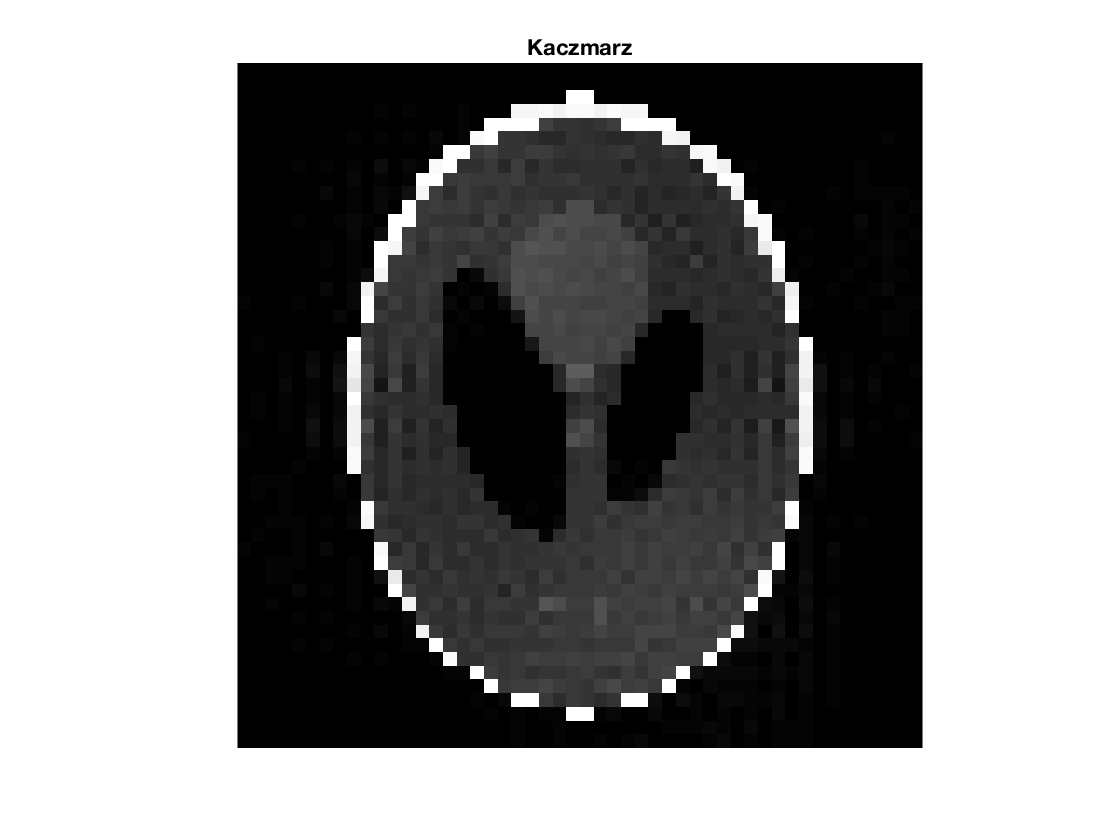



Xkacz = kaczmarz(A,b,k);

% Show the Kaczmarz solution.
% subplot(2,2,2)
subplot()
imagesc(reshape(Xkacz,N,N)), colormap gray, axis image off
caxis(c)
title('Kaczmarz')

## Perform the symmetric Kaczmarz iterations.

fprintf(1,'Perform k = %2.0f iterations with the symmetric Kaczmarz method.\n',k);

Perform k = 10 iterations with the symmetric Kaczmarz method.


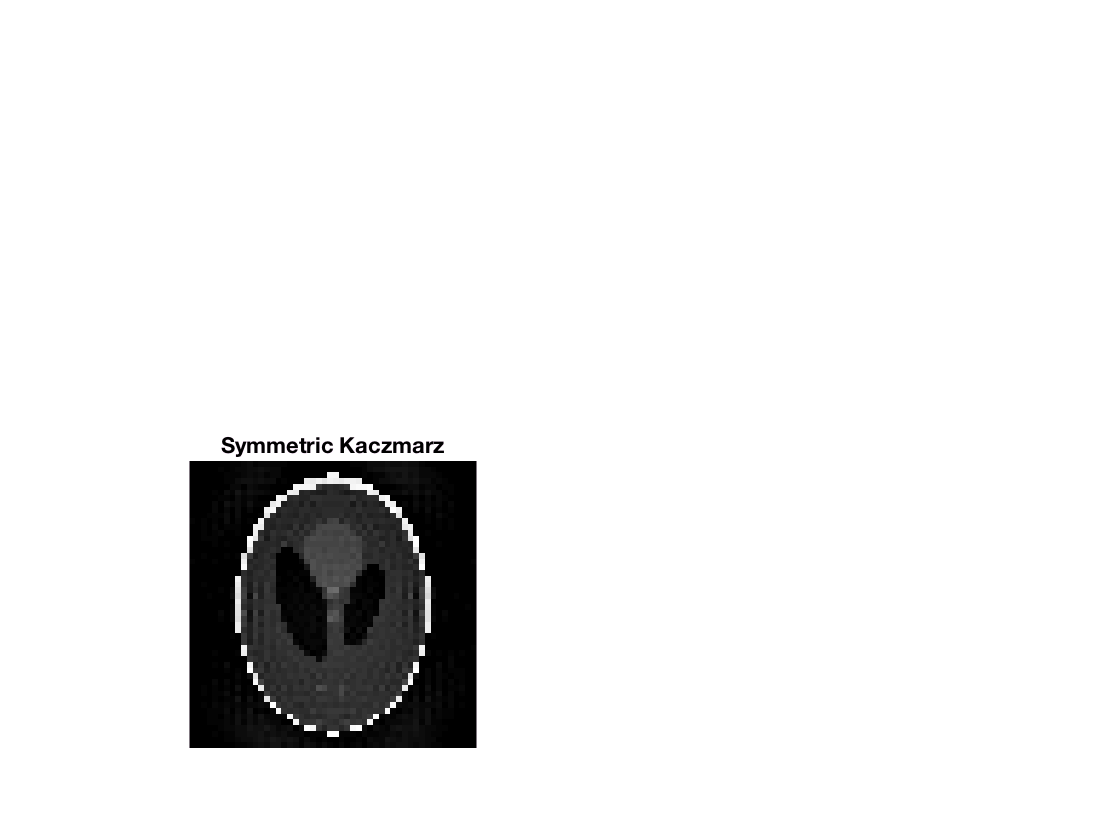


Xsymk = symkaczmarz(A,b,k);

% Show the symmetric kaczmarz solution.
% subplot(2,2,3)
subplot()
imagesc(reshape(Xsymk,N,N)), colormap gray, axis image off
caxis(c)
title('Symmetric Kaczmarz')

## Perform the randomized Kaczmarz iterations.

fprintf(1,'Perform k = %2.0f iterations with the randomized Kaczmarz method.\n',k);

Perform k = 10 iterations with the randomized Kaczmarz method.



[Xrand, info] = randkaczmarz(A,b,k,x0,struct('verbose', 10,'waitbar',true));

1/10:  resnorm=2.70e+01  relaxpar=1.00e+00  time(iter/total)=4.32e-01/1.15e+00 secs.
10/10:  resnorm=2.23e+00  relaxpar=1.00e+00  time(iter/total)=1.84e-01/2.76e+00 secs.


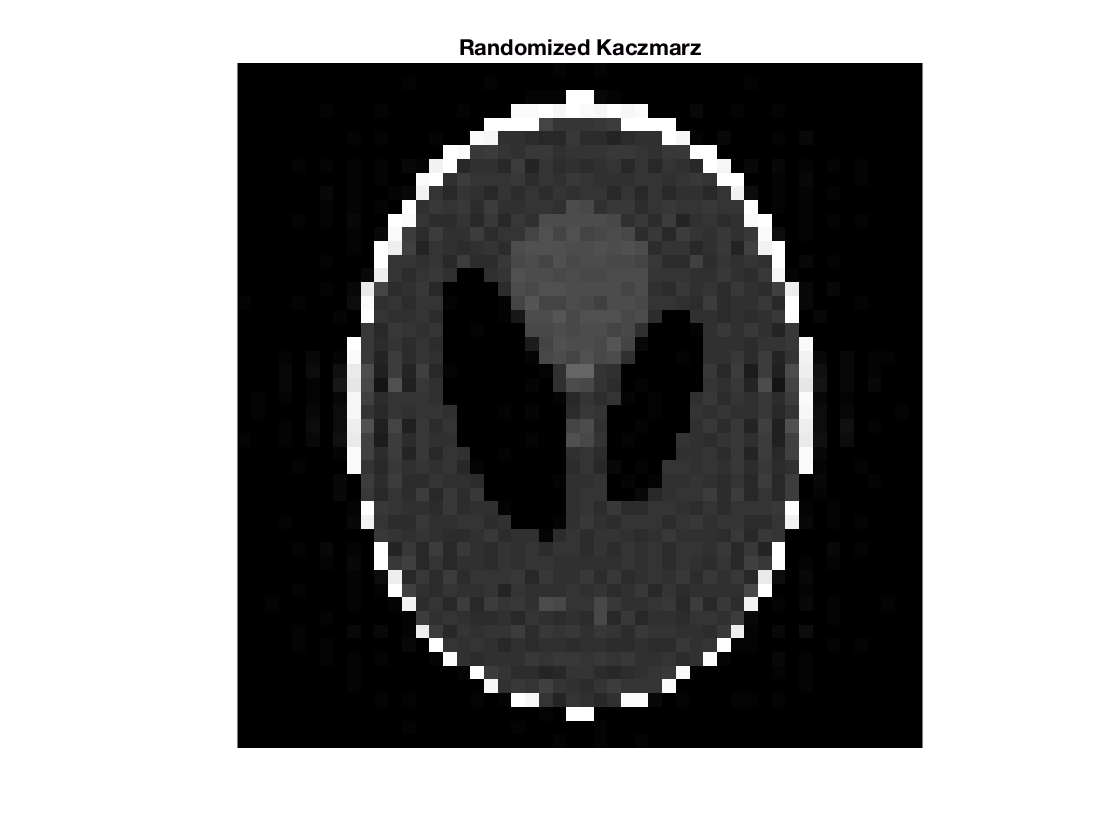


% Show the randomized Kaczmarz solution.
% subplot(2,2,4)
subplot()
imagesc(reshape(Xrand,N,N)), colormap gray, axis image off
caxis(c)
title('Randomized Kaczmarz')

info

info = struct with fields:
     stoprule: 0
    finaliter: 10
     relaxpar: 1
    itersaved: 10
    timetaken: 3.1608


## SK

fprintf(1,'Perform k = %2.0f iterations with the randomized Kaczmarz method.\n',k);

Perform k = 10 iterations with the randomized Kaczmarz method.



[Xrand, info] = art('SK',A,b,k,x0,struct('verbose', 10,'waitbar',true));

1/10:  resnorm=1.81e+01  relaxpar=1.00e+00  time(iter/total)=5.22e-01/1.31e+00 secs.
10/10:  resnorm=8.77e-01  relaxpar=1.00e+00  time(iter/total)=2.57e-01/3.43e+00 secs.


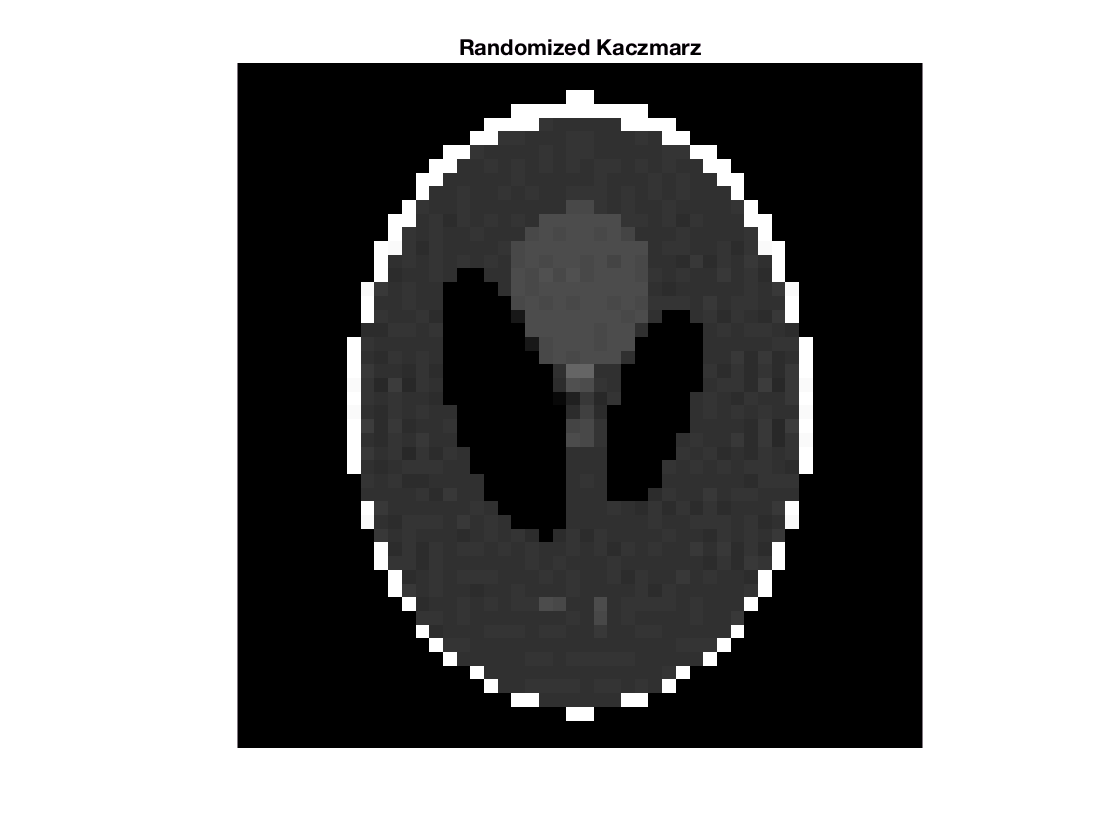

subplot()
imagesc(reshape(Xrand,N,N)), colormap gray, axis image off
caxis(c)
title('SK')

info

info = struct with fields:
     stoprule: 0
    finaliter: 10
     relaxpar: 1
    itersaved: 10
    timetaken: 3.9929


## RSK

fprintf(1,'Perform k = %2.0f iterations with the randomized Kaczmarz method.\n',k);

Perform k = 10 iterations with the randomized Kaczmarz method.



[Xrand, info] = art('RSK',A,b,k,x0,struct('verbose', 10,'waitbar',true));

1/10:  resnorm=2.00e+01  relaxpar=1.00e+00  time(iter/total)=5.49e-01/1.56e+00 secs.
10/10:  resnorm=9.24e-01  relaxpar=1.00e+00  time(iter/total)=1.83e-01/3.30e+00 secs.


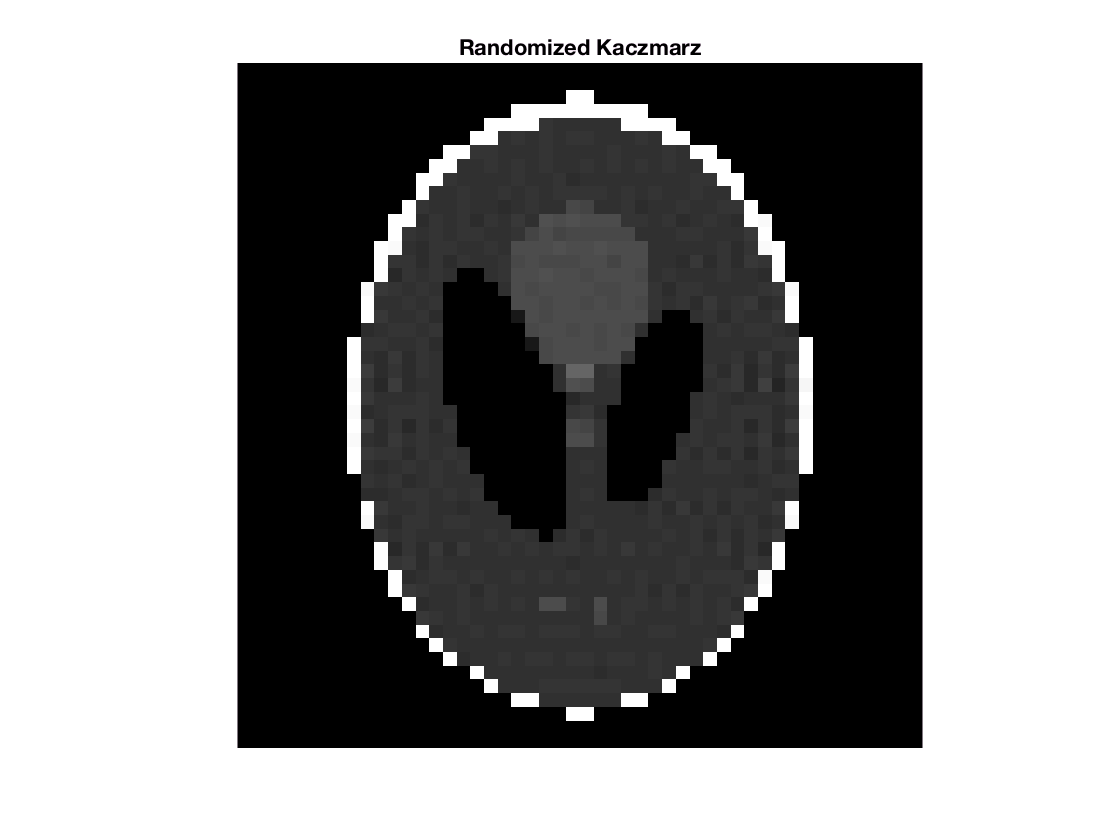

subplot()
imagesc(reshape(Xrand,N,N)), colormap gray, axis image off
caxis(c)
title('RSK')

info

info = struct with fields:
     stoprule: 0
    finaliter: 10
     relaxpar: 1
    itersaved: 10
    timetaken: 3.6842
